Robot 1 - 3 GDL Angulares

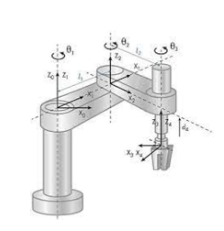

En este robot podemos notar 3 grados de libertad rotacionales, es por eso su importancia en la declaración de RP con sus valores especificos, de igual forma nuestras variables son theta 1,2,3. Debido a que existen desplazamientos constantes de nuestro robot, declaramos estas variables como constantes y al no ser afectadas directamente con una velocidad, solo aparecerán dentro de nuestras matrices de transformacion globales.

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) t d1 l2 l3 d4

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP =[0 0 0];

%Creamos el vector de coordenadas articulares
Q = [th1 th2 th3];

%Creamos el vector de velocidades generalizadas
Qp = diff(Q, t);

%Número de grado de libertad del robot
GDL = size(RP,2);
GDL_str = num2str(GDL);

Para declarar nuestras articulaciones, tomamos planteamos que nuestro plano cartesiano está con z perpendicular a nuestra rotacion, por lo que el cambio de posicion es un dezplazamiento constante d1 y rotacional para x,y estos con sus respectivos coseno y seno, Para el dezplazamiento rotacional solo z se encuentra en movimiento, por lo que colocamos su matriz correspondiente. 

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [cos(th1); sin(th1); d1];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1) 0;
           sin(th1)  cos(th1) 0;
           0 0 1];

Respecto a nuestra segunda articulación, tenemos solo un dezplazamiento de l2 y el angular, que es igualmente afectado por el angulo que exista en nuestra articulación anterior, por eso debemos realizar la suma de valores angular (theta), estas rotaciones son multiplicadas por l2 debido a que esta es la distancia que las afecta. Para la rotacion, solo existe mediante z y colocamos su matriz correspondiente.

%Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th1+th2); l2*sin(th1+th2); 0];
%Matriz de rotación de la junta 2 respecto a 1
R(:,:,2)= [cos(th2) -sin(th2) 0;
           sin(th2)  cos(th2) 0;
           0 0 1];

Nuestra ultima rotacion tiene igualmente un desplazamiento x,y y como constante un movimiento d4 que afecta la posicion final. Para nuestros desplazamientos, tomamos en cuenta nuestras rotaciones del eje anterior y el actual, con eso podemos obtener multiplicado por la distancia l3 nuestras posiociones acutales, mas z como constante d4. Nuestra matriz rotacional es solo en z por lo que colocamos su matriz correspondiente

%Articulación 3
%Posición de la articulación 3 respecto a 1
P(:,:,3)= [l3*cos(th2+th3); l3*sin(th2+th3); d4];
%Matriz de rotación de la junta 3 respecto a 1
R(:,:,3)= [cos(th3) -sin(th3) 0;
           sin(th3)  cos(th3) 0;
           0 0 1];

Se generar las matrices de trasnformación homogeneas globales y locales, se utiliza igualmente un Vector de relleno para completar la matriz y que no genere errores en calculos.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);
%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Se inicializan los valores de los vectores de posición y de rotación (vistos desde el marco de referencia inercial).

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

Se crean mediante un loop de los GDL el calculo de las matricez de transformacion locales de cada junta y posterior calcular la Global a partir de la local anterior.

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
for i = 1:GDL
    i_str= num2str(i);   
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   
   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
end

Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, cos(th1(t)) \
|                                           |
| sin(th1(t)),  cos(th1(t)), 0, sin(th1(t)) |
|                                           |
|      0,            0,      1,      d1     |
|                                           |
\      0,            0,      0,      1      /



Matriz de Transformación global T2


/ #3, -#2, 0, cos(th1(t)) + l2 cos(#1) \
|                                      |
| #2,  #3, 0, sin(th1(t)) + l2 sin(#1) |
|                                      |
|  0,  0,  1,            d1            |
|                                      |
\  0,  0,  0,             1            /

where

   #1 == 2 th1(t) + th2(t)

   #2 == sin(th1(t) + th2(t))

   #3 == cos(th1(t) + th2(t))




Matriz de Transformación global T3


/ #2, -#1, 0, cos(th1(t)) + l3 cos(#3) + l2 cos(2 th1(t) + th2(t)) \
|                                                                  |
| #1,  #2, 0, sin(th1(t)) + l3 sin(#3) + l2 sin(2 th1(t) + th2(t)) |
|                                                                  |
|  0,  0,  1,                        d1 + d4                       |
|                                                                  |
\  0,  0,  0,                           1                          /

where

   #1 == sin(th1(t) + th2(t) + th3(t))

   #2 == cos(th1(t) + th2(t) + th3(t))

   #3 == th1(t) + 2 th2(t) + th3(t)




Estas matrices demuestran el correcto resultado de nuestras transformaciones globales, podemos ver que d1 y d4 existen porque son constantes de movimiento y los cambios importantes en nuestra ultima matriz global con multiples movimientos afectados solo por l2 y l3 en posiociones de x,y. Respecto a lo rotacional, tenemos el resultado de nuestras matrices con rotacion en z, indicando especificamente que generan angulos en x,y. 

Calculamos los Jacobianos, usamos el metodo lineal con diferenciacion. Lo que nos genera 9 derivadas parciales por los 3 ejes. Como resultado, obtenemos la matriz de resultados en Jv_d y lo imprimimos.

Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
%Derivadas parciales de y respecto a th1, l2 y l3
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
%Derivadas parciales de z respecto a th1, l2 y l3
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);
%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13; 
              Jv21 Jv22 Jv23; 
              Jv31 Jv32 Jv33]); 
%Matriz Jacoviano Lineal
pretty(jv_d);

/ - sin(th1(t)) - l3 sin(#1) - l2 #3 2, - 2 l3 sin(#1) - l2 #3, -l3 sin(#1) \
|                                                                           |
|  cos(th1(t)) + l3 cos(#1) + l2 #2 2,   2 l3 cos(#1) + l2 #2,   l3 cos(#1) |
|                                                                           |
\                   0,                             0,                0      /

where

   #1 == th1(t) + 2 th2(t) + th3(t)

   #2 == cos(2 th1(t) + th2(t))

   #3 == sin(2 th1(t) + th2(t))




Procedemos a calcularlo analiticamente mediente un ciclo for para poder obtener las velocidades angulares y lineales. Debido a que existen primeros casos debemos colocar un try para no tomar en cuenta posiciones fuera del array, es decir, i-1.

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);
for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);


Una vez finalizados los jacobianos podemos obtener las velocidaddes angular y lineales solo multiplicando por nuestro Qp. 

%Velocidad lineal obtenida mediante el Jacobiano lineal
V=simplify (Jv_a*Qp');
pretty(V);

/ - #4 (l3 sin(#1) + l2 sin(#2)) - #5 (sin(th1(t)) + l3 sin(#1) + l2 sin(#2)) - l3 #3 sin(#1) \
|                                                                                             |
|  #4 (l3 cos(#1) + l2 cos(#2)) + #5 (cos(th1(t)) + l3 cos(#1) + l2 cos(#2)) + l3 #3 cos(#1)  |
|                                                                                             |
\                                              0                                              /

where

   #1 == th1(t) + 2 th2(t) + th3(t)

   #2 == 2 th1(t) + th2(t)

         _________
          d
   #3 == -- th3(t)
         dt

         _________
          d
   #4 == -- th2(t)
         dt

         _________
          d
   #5 == -- th1(t)
         dt





%Velocidad angular obtenida mediante el Jacobiano angular
W=simplify (Jw_a*Qp');
pretty(W);

/                 0                 \
|                                   |
|                 0                 |
|                                   |
| _________   _________   _________ |
|  d           d           d        |
| -- th1(t) + -- th2(t) + -- th3(t) |
\ dt          dt          dt        /



Es importante analizar los resultados debido a que esto expone el correcto funcionamiento de nuestro robot, estas matrices demuestran correctamente nuestros resultados debido a que las velocidades lineales son solamente en x,y, eso demuestra que al no haber realizado un cambio de ejes, podemos conocer los cambios de velocidad que no son afectados en z debido a que no tenemos desplazamiento, solo constantes dde moviemito. 

Respecto a nuestra matriz de rotacion, es exactamente el valor que deberia tener ya que nuestras 3 articulaciones tienen a z perpendicular a su rotacion, eso demuestra que los cambios de velocidad angular solo existen en z. 